# Model the Heat Tolerance of Components Exposed to Electronics

This finite element thermal analysis (FEA) examines the heat tolerance for a piston designed for a gasoline engine.

A single domain heat conduction analysis is performed on the piston. 

## Import the geometry

In the cylinder, the piston is exposed to the heat coming from the combustion occurring above the piston top surface and from the cylinder lateral walls that are being cooled down by the cooling system. Here we will create the pde model, import the STL file of the piston, and plot it.

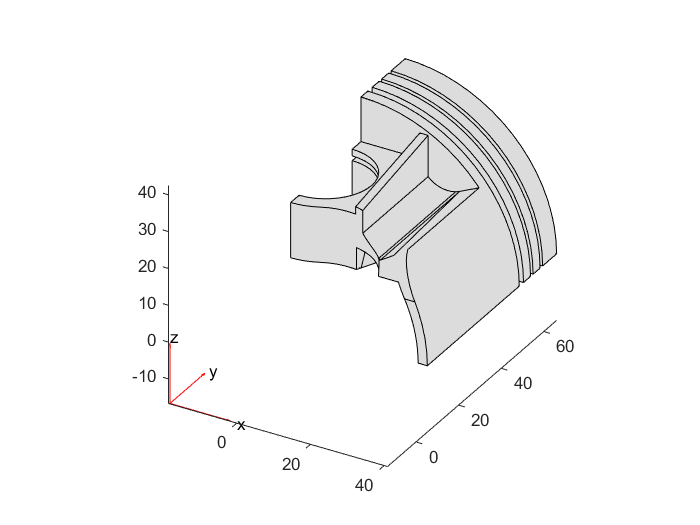

thermalmodel = createpde('thermal','steadystate');
importGeometry(thermalmodel,'qPiston.stl');
pdegplot(thermalmodel, 'FaceAlpha',1)

## Mesh the Geometry and Determine the Part size                               

From the supplied dimensions above we can estimate the part height should be approximatly 61mm. Create and visualize a tetrahedral mesh of the component with a maximum value of 1.5mm.

tic
generateMesh(thermalmodel, 'Hmax', 1.5);
timeToMesh = toc

timeToMesh = 2.4018

thermalmodel.Mesh

ans =   FEMesh with properties:

             Nodes: [3×120163 double]
          Elements: [10×80384 double]
    MaxElementSize: 1.5000
    MinElementSize: 0.7500
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


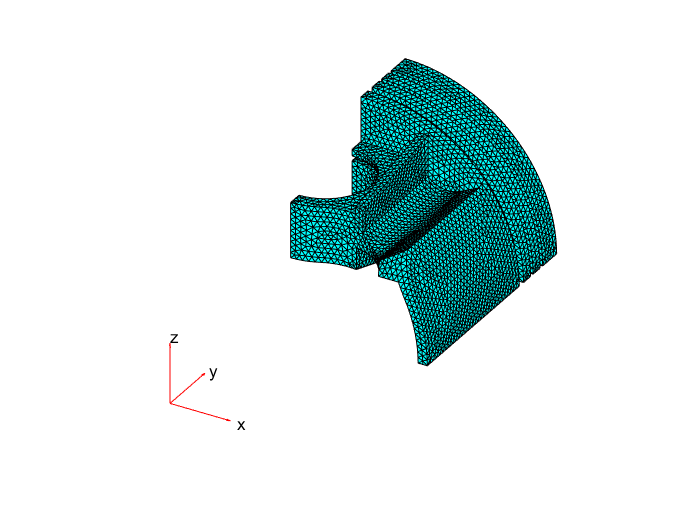

pdemesh(thermalmodel)

Measure the dimensions of the mesh.

xLength = max(thermalmodel.Mesh.Nodes(1,:)) - min(thermalmodel.Mesh.Nodes(1,:))

xLength = 41.1250

yLength = max(thermalmodel.Mesh.Nodes(2,:)) - min(thermalmodel.Mesh.Nodes(2,:))

yLength = 60.8000

zLength = max(thermalmodel.Mesh.Nodes(3,:)) - min(thermalmodel.Mesh.Nodes(3,:))

zLength = 41.1250

## Setup the Material Properties 

The material is assumed to be an aluminum alloy and to have a thermal conductivity of $175\ldotp 728\;\frac{W}{m\;K}$.

tc = .175728;

Now remove the units to obtain the value for the thermal properties. 

thermalProperties(thermalmodel,'Cell',1,'ThermalConductivity',tc, 'MassDensity', 2.7*1e-6, 'SpecificHeat', 837.359638); 

## Set up the Boundary Conditions

The boundary conditions for this model are taken from a thesis already done on a piston designed for diesel engine operation conditions. If we can find the conditions measures for gasoline engine operating conditions then we should replace the current available data.

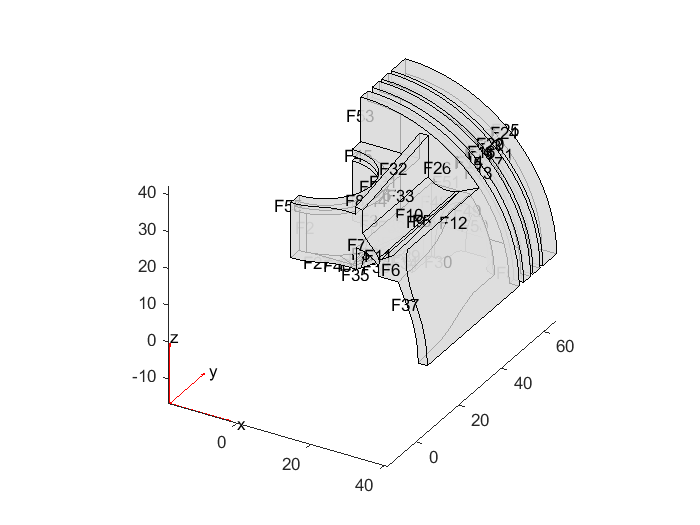

pdegplot(thermalmodel,'FaceLabels','on', 'FaceAlpha',0.75)

Different faces present on the piston are assigned different convection coefficients. The considered surface and there corresponding convection coefficients are:

- **Combustion Zone: **h = 350.6 W/m^2K   ;   T = 638.3 K

- **Top Land: **h = 230 W/m^2K    ;   T = 573 K

- **Rings: **h = 625 W/m^2K ;   T = 345.5 K

- **2nd and 3rd Lands: **h = 115 W/m^2K   ;   T = 345.5

- **Skirt Outisde: **h = 60 W/m^2K  ;   T = 383 K

- **Skirt Inside:** h = 162 W/m^2K  ;   T = 383 K

- **Combustion Underside: **h = 608 W/m^2K  ;   T = 383 K

% thermalBC(thermalmodel, 'Face', [38 91 92], 'HeatFlux', .3537);
% thermalBC(thermalmodel, 'Face', [27 29 31 33 35 37], 'HeatFlux', -0.1061);
% thermalBC(thermalmodel, 'Face', 25, 'HeatFlux', -0.03537);
% thermalBC(thermalmodel, 'Face', [40 46 81 87 89], 'HeatFlux', -0.1875);
T1 = 638.3;
q1 = .3537;
h1 = q1/T1;
thermalBC(thermalmodel,'Face', 51, 'ConvectionCoefficient', h1, 'AmbientTemperature', T1);
T2 = 573;
h2 = 0.07*q1/T2;
thermalBC(thermalmodel, 'Face', 24, 'ConvectionCoefficient', h2, 'AmbientTemperature', T2);
T3 = 345.5;
h3 = 0.19*q1/T3;
thermalBC(thermalmodel, 'Face', [13 17 21], 'ConvectionCoefficient', h3, 'AmbientTemperature', T3);
T4 = 345.5;
h4 = 0.04*q1/T4;
thermalBC(thermalmodel, 'Face', [16 20], 'ConvectionCoefficient', h4, 'AmbientTemperature', T4);
T5 = 345.5;
h5 = 0.1*q1/T5;
thermalBC(thermalmodel, 'Face', 12, 'ConvectionCoefficient', h5, 'AmbientTemperature', T5);
T6 = 383;
h6 = 0.11*q1/T6;
thermalBC(thermalmodel, 'Face', 30, 'ConvectionCoefficient', h6, 'AmbientTemperature', T6);
T7 = 383;
h7 = 0.42*q1/T7;
thermalBC(thermalmodel, 'Face', 50, 'ConvectionCoefficient', h7, 'AmbientTemperature', T7);

The bottom face is given a fixed temperature assuming that the rest of the robotic arm acts as a heat sink.

## Solve the FEA analysis

Solve the model and calculate the max and bulk body temperatures. Time how long the solve takes.

tic
results = solve(thermalmodel);
time = toc

time = 9.6365

## Post-process the Results

Compute the max temperature in $K$ and rewrite that to $C^{\circ }$.

t_max = max(results.Temperature)

t_max = 524.9787

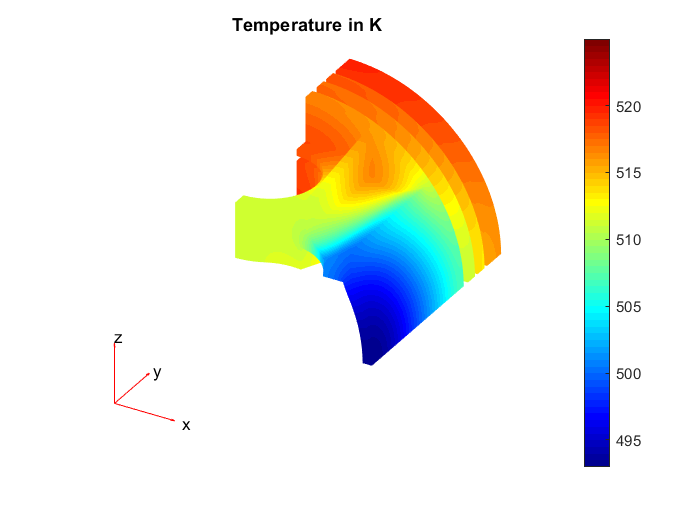

pdeplot3D(thermalmodel,'ColorMapData',results.Temperature)
title('Temperature in K')
colorbar

## Structural Analysis due to Thermal Load

### Create a static structural model.

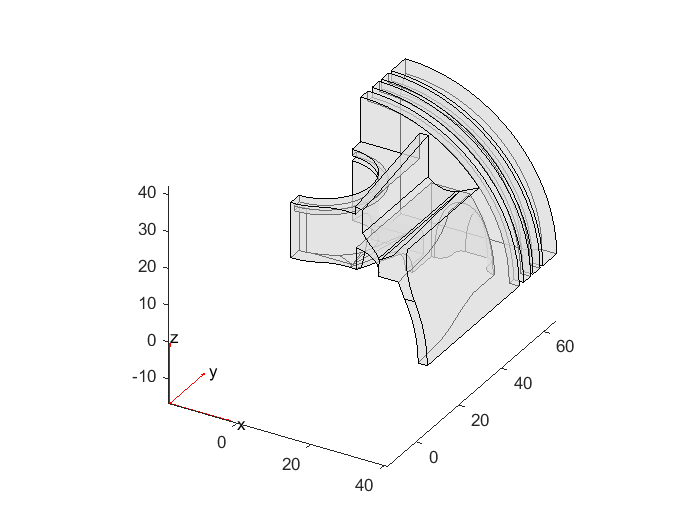

thermalstructuralmodel = createpde('structural', 'static-solid');
importGeometry(thermalstructuralmodel, 'qPiston.stl');
pdegplot(thermalstructuralmodel, 'FaceAlpha',0.5)

### Generate Mesh

tic
generateMesh(thermalstructuralmodel, 'Hmax', 1.5)

ans =   FEMesh with properties:

             Nodes: [3×120163 double]
          Elements: [10×80384 double]
    MaxElementSize: 1.5000
    MinElementSize: 0.7500
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


toc

Elapsed time is 2.276231 seconds.


pdemesh(thermalstructuralmodel)

### Setup Material Structural Properties

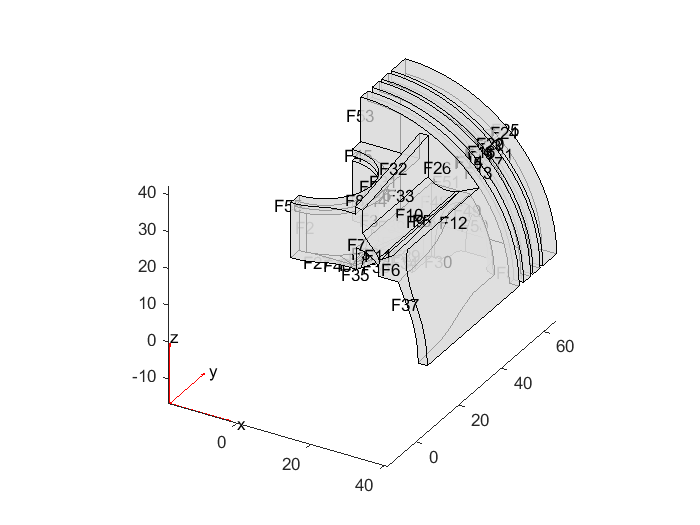

pdegplot(thermalstructuralmodel,'FaceLabels','on', 'FaceAlpha',0.7)

structuralProperties(thermalstructuralmodel, 'Cell', 1, 'YoungsModulus', 67*1e9, 'PoissonsRatio', 0.33, 'CTE', 23*1e-6);
% structuralBC(thermalstructuralmodel, 'Face', 3, 'Constraint', 'fixed');
structuralBC(thermalstructuralmodel, 'Face', [53 54 55], 'Constraint', 'symmetric');
structuralBodyLoad(thermalstructuralmodel, "Temperature", results);
thermalstructuralmodel.ReferenceTemperature = 450;
tic
thermalstructuralresults = solve(thermalstructuralmodel)

thermalstructuralresults =   StaticStructuralResults with properties:

      Displacement: [1×1 struct]
            Strain: [1×1 struct]
            Stress: [1×1 struct]
    VonMisesStress: [120163×1 double]
              Mesh: [1×1 FEMesh]


toc

Elapsed time is 274.181341 seconds.


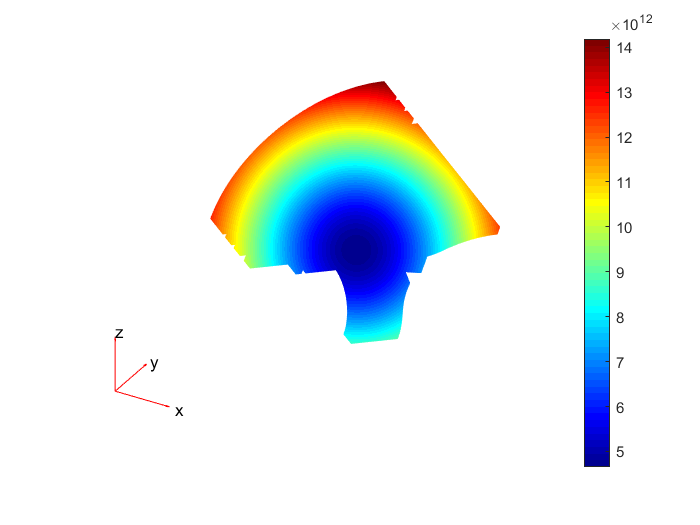

pdeplot3D(thermalstructuralmodel,'ColorMapData',thermalstructuralresults.Displacement.Magnitude, ...
                          'Deformation',thermalstructuralresults.Displacement, ...
                          'DeformationScaleFactor',1)

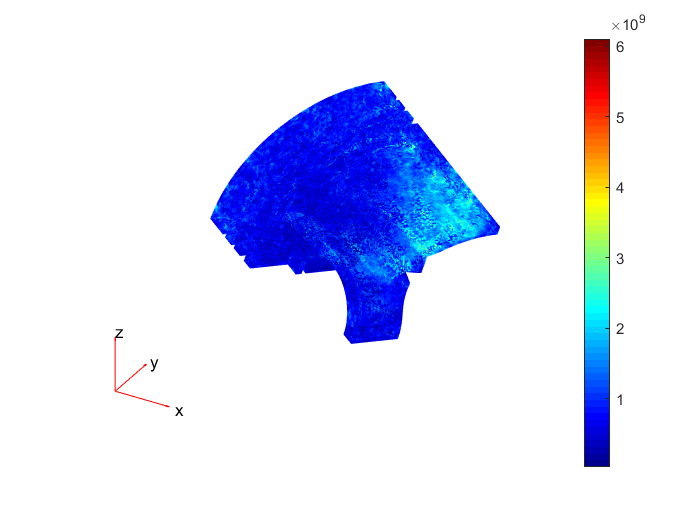

pdeplot3D(thermalstructuralmodel,'ColorMapData',thermalstructuralresults.VonMisesStress,'Deformation',thermalstructuralresults.Displacement,'DeformationScaleFactor',10)

## Structural Analysis due to Gas Pressure

### Create a static structural model.

structuralmodel = createpde('structural', 'static-solid');
importGeometry(structuralmodel, 'qPiston.stl');
pdegplot(structuralmodel, 'FaceAlpha',0.5)

### Generate Mesh

tic
generateMesh(structuralmodel, 'Hmax', 1.5)
toc
pdemesh(structuralmodel)

### Setup Material Structural Properties

Here we first set all the face to have 0 displacements in lateral directions X and Z and then we fix the face of the pin hole and the other face are symmetric due to the adoption of a quarter model. The load applied is a Surfacetraction force; in other words, pressure applied on the top surface expressed in Pa and on the bottom surfaces we can put the environmental pressure (needs to be discussed).

structuralProperties(structuralmodel, 'Cell', 1, 'YoungsModulus', 67*1e3, 'PoissonsRatio', 0.33, 'CTE', 23*1e-6);
structuralBC(structuralmodel, 'Face', 1:55, 'XDisplacement', 0);
structuralBC(structuralmodel, 'Face', 1:55, 'ZDisplacement', 0);
structuralBC(structuralmodel, 'Face', 3, 'Constraint', 'fixed');
structuralBC(structuralmodel, 'Face', [53 54 55], 'Constraint', 'symmetric');
structuralBoundaryLoad(structuralmodel, 'Face', [25 51 52], 'Surfacetraction', [0; -18; 0]);
tic
R = solve(structuralmodel);
toc

pdeplot3D(structuralmodel,'ColorMapData',R.Displacement.uy, ...
                          'Deformation',R.Displacement, ...
                          'DeformationScaleFactor',100)

## Thermo-Structural Results

total_results.Displacement.ux = R.Displacement.ux + thermalstructuralresults.Displacement.ux;
total_results.Displacement.uy = R.Displacement.uy + thermalstructuralresults.Displacement.uy;
total_results.Displacement.uz = R.Displacement.uz + thermalstructuralresults.Displacement.uz;
total_results.Displacement.Magnitude = sqrt(total_results.Displacement.ux.^2 + total_results.Displacement.uy.^2 + total_results.Displacement.uz.^2);

pdeplot3D(thermalstructuralmodel,'ColorMapData',total_results.Displacement.Magnitude, ...
                          'Deformation',total_results.Displacement, ...
                          'DeformationScaleFactor',10)
total_results.VonMisesStress = R.VonMisesStress + thermalstructuralresults.VonMisesStress;
pdeplot3D(thermalstructuralmodel,'ColorMapData',total_results.VonMisesStress,'Deformation',total_results.Displacement,'DeformationScaleFactor',10)